# Test on benchmark problems

In this example, we compare "swarmCBO" to the PSO implementation "particleswarm" of the MATLAB global optimization toolbox. We consider the Rastrigin and Ackley global optimization problems.

We start by defining the objective function:

rastrigin = @(x) 10.0 * size(x,2) + sum(x .^2 - 10.0 * cos(2 * pi .* x),2);
ackley = @(x) - 20*exp(-0.2*sqrt(1/size(x,2)* sum(x.^2,2))) - exp(1/size(x,2)* sum(cos(2*pi*x),2)) + 20 + exp(1);

fun = rastrigin;

We test the methods for different values of problem dimension $d=5,10,15,20$.

numtests = 10;

dims = (5:5:20)';
numdims =length(dims);

rng default  % For reproducibility

Next, we select the options for the algorithms. This can modified to set different paramters.

optionsCBO = optimoptions('particleswarm','Display','off', 'MinNeighborsFraction',1,'InertiaRange',[0,0]);
optionsPSO = optimoptions('particleswarm','Display','off');

We now perform the experiments and collect dat for visualization.

errorCBO = zeros(numtests,numdims);
errorPSO = zeros(numtests,numdims);

for nd = 1:numdims
    nvars = dims(nd);
    lb = -10*ones(1,nvars);  %set lower bound
    ub = 10*ones(1,nvars);   %set upper bound

    for nt  = 1:numtests
        xCBO = swarmCBO(fun,nvars,lb,ub,optionsCBO);
        errorCBO(nt,nd) = max(abs(xCBO));
        xPSO = particleswarm(fun,nvars,lb,ub,optionsPSO);
        errorPSO(nt,nd) = max(abs(xPSO));
    end
end

Now, we visualize the median values obtained.

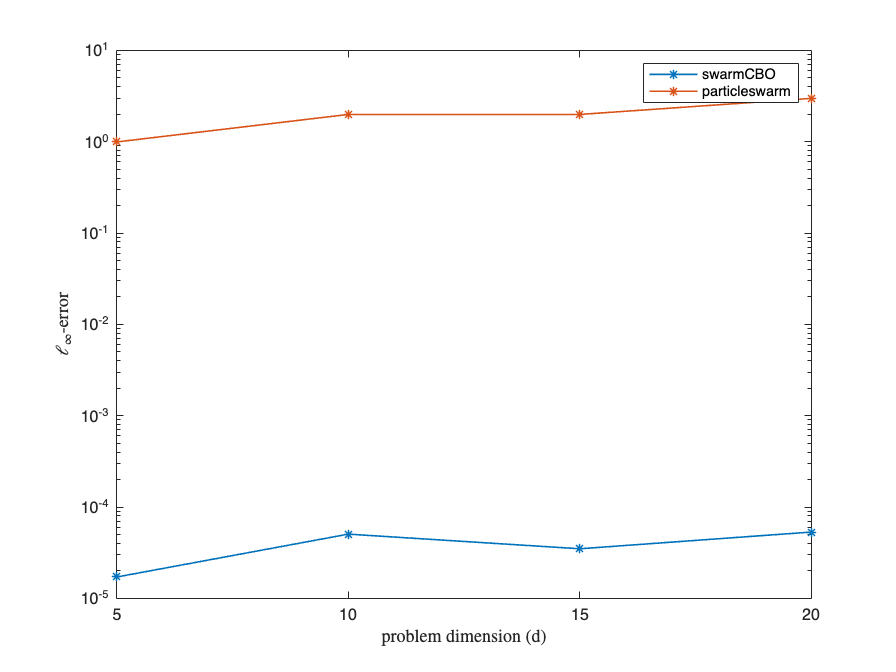

figure;

errorCBO_median = median(errorCBO,1);
semilogy(dims,errorCBO_median,'-*','DisplayName','swarmCBO');
hold on

errorPSO_median = median(errorPSO,1);
semilogy(dims,errorPSO_median,'-*','DisplayName','particleswarm');
ylabel('$\ell_\infty$-error', 'Interpreter','latex')
xlabel('problem dimension (d)', 'Interpreter','latex')
legend